# indentPlot

This live script is continuation of calciumPlot.mlx and applied to the indentation stimuli

#### Load the indenter stimulation file

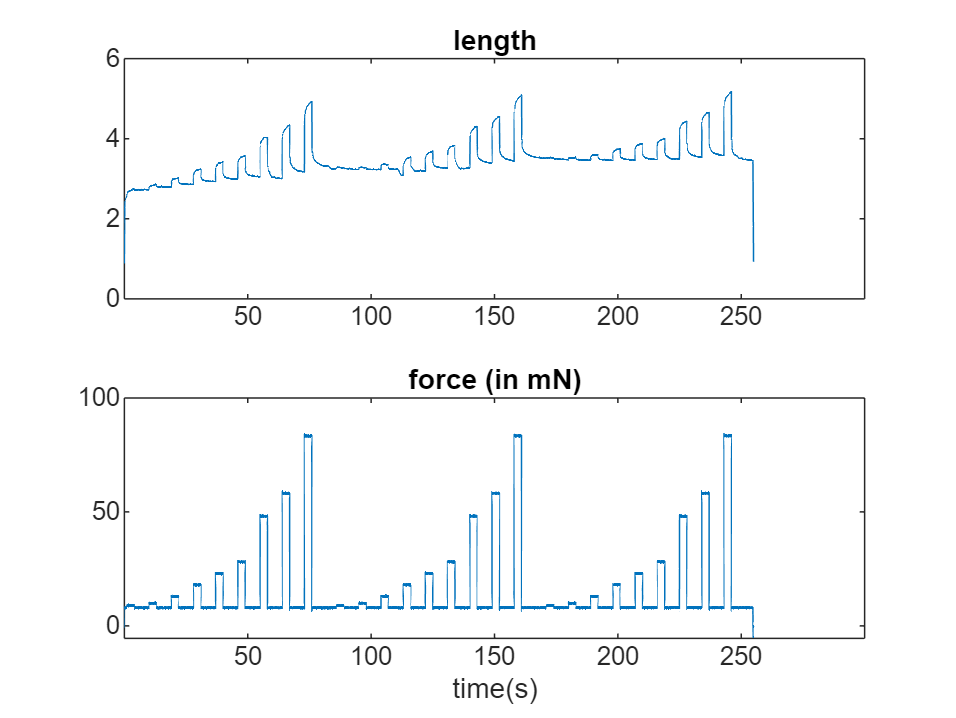

folderNameTemp = strsplit(path,filesep);
folderName = folderNameTemp{end-1};
clear folderNameTemp
[filenameMat,pathMat] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Qi\stimulation\indenter\*.mat',...
    ['select an indentation file for   ', folderName]);

% [filenameMat,pathMat] = uigetfile('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging\stimulation\indenter\*.mat', ...
%     ['select an indentation file for
load([pathMat,filenameMat])
force = data(:,3);
down = 10;
figure,
tick = floor(numel(force)/Fs/5/10)*10;
% subplot(311),plot(cameraTrigger(1:10:end)),title('Trigger'),
subplot(211),plot(data(1:down:end,2)),title("length");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
subplot(212),plot(data(1:down:end,3)*50),title("force (in mN)");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
xlabel('time(s)')

% plot(force),title("force")
% pbaspect([3 1 1])
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% nUnit = ceil(length(I)/nSweep);

#### Split the indenter file

if ~exist ('interSweepInterval', 'var')
    interSweepInterval = 10; % if interSweepInterval is not saved, then manually define it
end

if ~exist('numSweeps', 'var')
    numSweeps = 3;
end

% split the intendation file by sweeps
if ~exist('decayTime', 'var')
    % this is for the old indentation file without saving the
    % indentIntervalTime info
    %cut out the interSweepInterval and split the indentation into "nSweep" part
    indentUnit = length(force) / numSweeps - interSweepInterval * Fs;
    forceSplit = zeros (indentUnit, numSweeps);
    for i = 1:numSweeps
        indentStart = length(force) / numSweeps * (i-1) +1;
        indentEnd = indentStart + indentUnit - 1;
        forceSplit(:,i) = force(indentStart:indentEnd);
    end
    clear indentUnit indentStart indentEnd i
    
else
    % cut out the interSweepInterval and indentIntervalTime, then split the indentation into "nSweep" part
    indentOn = baseline + indentTime + decayTime;
    indentUnit = length(force) / numSweeps - interSweepInterval * Fs;
    indentSubUnit = indentUnit/numel(intensities) - indentIntervalTime * Fs;
    if indentSubUnit ~= (indentOn * Fs)
        error ('Something wrong with the indentation format');
    end
    
    forceSplitPre = zeros(indentSubUnit,numel(intensities), numSweeps);
    
    for i = 1:numSweeps
        indentStart = length(force) / numSweeps * (i-1) +1;
        indentEnd = indentStart + indentUnit - 1;
        indentBySweep = force(indentStart:indentEnd);
        for j = 1: numel(intensities)
            indentSubStart = indentUnit/ numel(intensities) * (j-1) +1;
            indentSubEnd = indentSubStart + indentSubUnit -1;
            forceSplitPre(:, j, i) = indentBySweep(indentSubStart:indentSubEnd);
        end
    end
    forceSplit = reshape(forceSplitPre, indentSubUnit * numel(intensities), numSweeps);
    clear indentUnit indentSubUnit indentStart indentEnd indentSubStart indentSubEnd forceSplitPre i j
end

####  Align the indentation with response and save the figure

nCell = 1

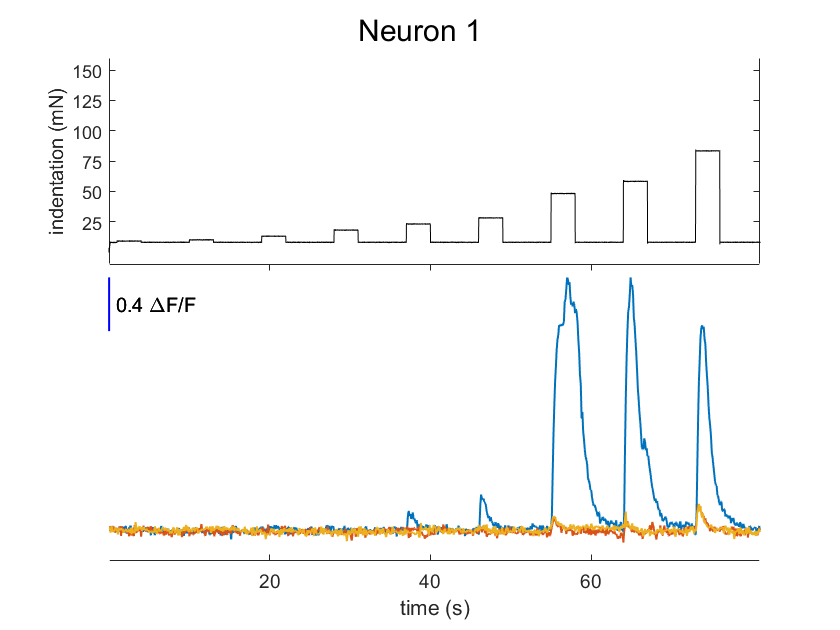

nCell = 2

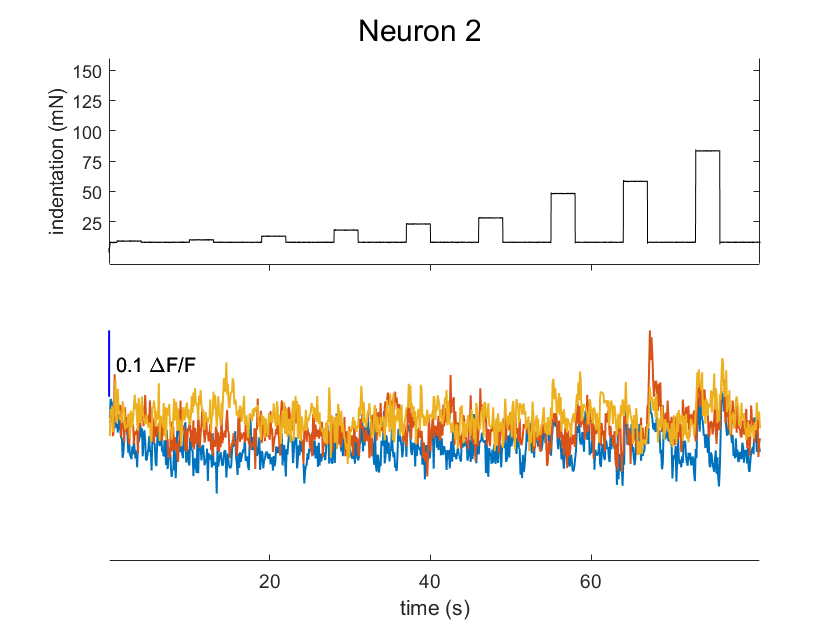

nCells = 1:2;
for j = 1: numel(nCells)
    nCell = nCells(j)
    normDeltaFncell = normDeltaF(:,nCell);
    m = length(normDeltaFncell);
    nUnit = floor(m/numSweeps);

    %% split the calcium trace by sweeps
    Split = zeros(nUnit, numSweeps);

    for i = 1:numSweeps
        Start = nUnit * (i-1) + 1;
        End = Start+nUnit-1;
        if End > m
            Split(1:m-Start+1,i) = normDeltaFncell(Start:end);
        else
            Split(:,i) = normDeltaFncell(Start:Start+nUnit-1);
        end
    end

    gap = 0.8 ;
    for i = 1:numSweeps
        Split(:,i) = Split(:,i) - mean(Split(1:baseline * fps,i));
        %Split(:,i) = Split(:,i) + max(normDeltaFncell) * gap * (numSweeps-i);
    end


    %% Do the plotting
    fh = figure;
    set(gcf,'Visible','on')

    sfh1 = subplot(211); p = plot(forceSplit(:,1));  set(p,'Color','black');
    %set(p,'LineWidth',1) %set(gca,'xtick',[]);
    set(sfh1,'xcolor',[1 1 1]); xlim([0 size(forceSplit,1)])
    if max(forceSplit(:)) > 1.4 && max(forceSplit(:)) <1.6 % that is for the normal 75 mN
        ylim([-0.2 2])
        yticks([0.5:0.5:2]);
        yticklabels(["25" "50" "75" "100"]);
    elseif  max(forceSplit(:)) > 1.6
        ylim([-0.2 3.2])
        yticks([0.5:0.5:3]);
        yticklabels(["25" "50" "75" "100" "125" "150"]);
    else
        ymax = (ceil( max(forceSplit(:)) *10 ))/10 + 0.1;
        ylim([-0.1 0.9])
        yticks([0.2:0.2:ymax])
        yticklabels(["10" "20" "30" "40"]);
    end

    %axis off
    ylabel("indentation (mN)"); set(gcf,'color','w');

    sfh2 = subplot(212);

    if 1
        plot(Split,'LineWidth',1);
    else
        for i = 1: numSweeps
            findpeaks(Split(:,i), 'MinPeakProminence',0.1);
        end
    end

    maxy = max(Split(:)); xlim([0,nUnit]);
    ylim([min(normDeltaFncell(:))-0.15, maxy + 0.1]); set(gca,'ycolor',[1 1 1]);
    % yticks([0 gap gap*2])
    % yticklabels(["trial3" 'trial2' "trial1"]); % set(gca,'YTick',[])
    set(sfh2,'XTick',[200:200:700]); set(sfh2,'xticklabels',["20" "40" "60"]);
    xlabel("time (s)") % axis off
    sfh2.Position = sfh2.Position + [0 0 0 0.13];

    hold on
    if max(normDeltaFncell)/4 > 0.1
        scaleLength = floor(max(normDeltaFncell)/4 * 10) /10;
    else
        scaleLength = 0.1;
    end

    x = [0.1 0.1]; y = [maxy-scaleLength maxy];
    plot(x, y, 'b', 'linewidth',1);
    textStr = [' ', num2str(scaleLength), ' \DeltaF/F'];
    text(x+1,[maxy-scaleLength/2 maxy-scaleLength/2], textStr)

    sgtitle(strcat("Neuron ",num2str(nCell)));
end

## Do the plotting (one subplot per sweep)

nCell = 1

xEnd = 50.1000

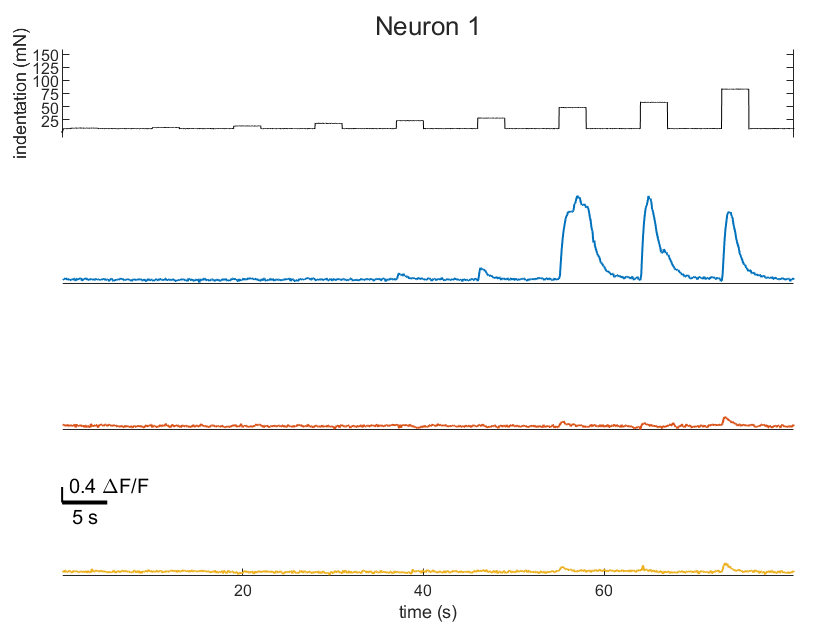

nCell = 2

xEnd = 50.1000

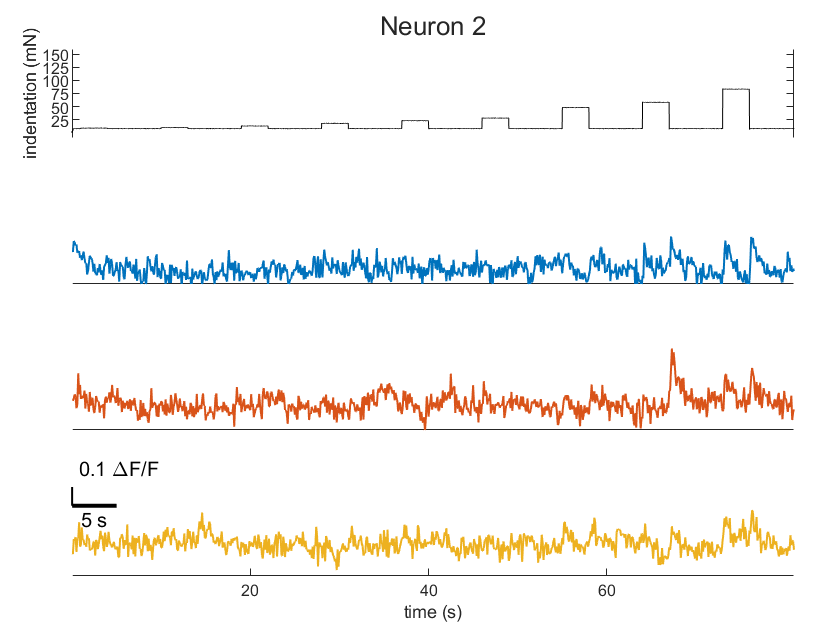

nCells = 1:2;
colors = lines(numSweeps);
outputFolder = strcat(path,filename(1:end-4));
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

savefigures = 0; %Change to save all the figures
for j = 1: numel(nCells)
    nCell = nCells(j)
    normDeltaFncell = normDeltaF(:,nCell);
    m = length(normDeltaFncell);
    nUnit = floor(m/numSweeps);

    %% split the calcium trace by sweeps
    Split = zeros(nUnit, numSweeps);

    for i = 1:numSweeps
        Start = nUnit * (i-1) + 1;
        End = Start+nUnit-1;
        if End > m
            Split(1:m-Start+1,i) = normDeltaFncell(Start:end);
        else
            Split(:,i) = normDeltaFncell(Start:Start+nUnit-1);
        end
    end

    gap = 0.8 ;
    for i = 1:numSweeps
        Split(:,i) = Split(:,i) - mean(Split(1:baseline * fps,i));
        %Split(:,i) = Split(:,i) + max(normDeltaFncell) * gap * (numSweeps-i);
    end

    fh = figure; set(fh,'Color','w'); set(fh,'Visible','on');

    % Compact vertical tiling: 1 row for force + one per sweep
    t = tiledlayout(numSweeps+1,1,'TileSpacing','compact','Padding','compact');

    % --- Force (top tile) ---
    axForce = nexttile(t,1);
    p = plot(forceSplit(:,1)); set(p,'Color','k');
    xlim([0 size(forceSplit,1)]);
    ylabel("indentation (mN)");
    set(axForce,'XColor',[1 1 1]); % hide x-axis ticks
    % your original force y-limits/ticks:
    if max(forceSplit(:)) > 1.4 && max(forceSplit(:)) < 1.6
        ylim([-0.2 2]); yticks(0.5:0.5:2); yticklabels(["25" "50" "75" "100"]);
    elseif max(forceSplit(:)) > 1.6
        ylim([-0.2 3.2]); yticks(0.5:0.5:3); yticklabels(["25" "50" "75" "100" "125" "150"]);
    else
        ymax = (ceil(max(forceSplit(:))*10))/10 + 0.1;
        ylim([-0.1 0.9]); yticks(0.2:0.2:ymax); yticklabels(["10" "20" "30" "40"]);
    end

    % --- Calcium (one axis per sweep) ---
    % Common x/y limits across all sweeps for visual comparability
    xlimCal = [0 nUnit];
    if max(Split(:)) < 0.1
        ylCal = [min(Split(:)), 0.6]
    else
        ylCal = [min(normDeltaFncell(:))-0.02, max(Split(:))+0.02];
    end

    axCal = gobjects(numSweeps,1);
    for i = 1:numSweeps
        axCal(i) = nexttile(t,i+1);
        plot(Split(:,i), 'LineWidth', 1, 'Color', colors(i,:));
        xlim(xlimCal); ylim(ylCal);
        set(axCal(i),'YColor',[1 1 1]); % optional: hide y-axis color
        if i < numSweeps
            set(axCal(i),'XTick',[]); % only bottom axis gets ticks/label
        else
            set(axCal(i),'XTick',200:200:700,'XTickLabel',["20" "40" "60"]);
            xlabel("time (s)");
        end
        ylabel(sprintf('trial %d', i));
        box off
    end

    % --- Simple ΔF/F scale bar on the bottom subplot ---
    maxy = ylCal(2)+0.05;
    if max(normDeltaFncell)/4 > 0.1
        scaleLength = floor(max(normDeltaFncell)/4 * 10)/10;
    else
        scaleLength = 0.1;
    end
    axes(axCal(end)); hold on
    plot([0.1 0.1],[maxy-scaleLength maxy],'k','LineWidth',1);
    text(1, maxy, [' ' num2str(scaleLength) ' \DeltaF/F']);

    % --- 5 s x-scale bar ---
    barLength = 5*fps;              % frames for 5 seconds
    % xEnd = nUnit - 20;              % right-side placement (adjust as needed)
    % xStart = xEnd - barLength;
    xStart = 0.1;
    xEnd = xStart + barLength        % a little above bottom
    plot([xStart xEnd],[maxy-scaleLength maxy-scaleLength],'k','LineWidth',2);
    text(mean([xStart xEnd]), maxy-scaleLength, '5 s', ...
        'HorizontalAlignment','center','VerticalAlignment','top');

    % Title
    sgtitle(sprintf('Neuron %d', nCell));
    if savefigures
        figureName = strcat(outputFolder,"\Aligned_Neuron",num2str(nCell),".pdf");
        exportgraphics(fh, figureName,"Resolution",300);
    end
end

## Select specific neuron and trace for one plot

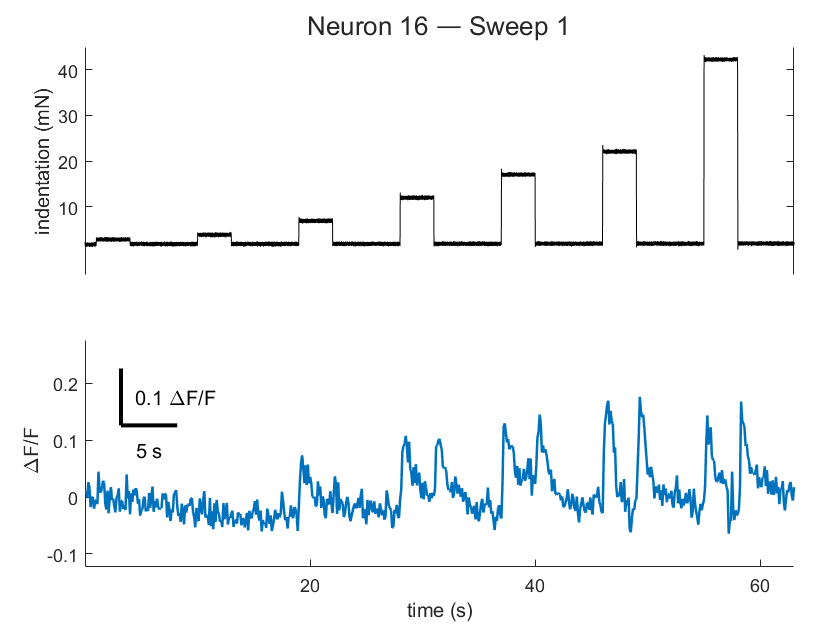

% ==== PARAMETERS ====
selectedNeuron = 10;    % which neuron
selectedSweep  = 1;    % which sweep

% ==== Get full trace for this neuron ====
normDeltaFncell = normDeltaF(:, selectedNeuron);
m = length(normDeltaFncell);
nUnit = floor(m/numSweeps);   % frames per sweep

% ==== Directly index into the chosen sweep ====
StartIdx = (selectedSweep-1)*nUnit + 1;
EndIdx   = StartIdx + nUnit - 1;
if EndIdx > m
    thisTrace = normDeltaFncell(StartIdx:end);
else
    thisTrace = normDeltaFncell(StartIdx:EndIdx);
end

% baseline subtract
thisTrace = thisTrace - mean(thisTrace(1:baseline*fps));

% ==== PLOT (force top, selected trace bottom) ====
fh = figure; set(fh,'Color','w'); set(fh,'Visible','on');
t = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

% --- Force (top) ---
axForce = nexttile(t,1);
% If you have force for each sweep, show the matching one; otherwise use (:,1)
if size(forceSplit,2) >= selectedSweep
    p = plot(forceSplit(:, selectedSweep), 'Color', 'k');
else
    p = plot(forceSplit(:, 1), 'Color', 'k');
end
xlim([0 size(forceSplit,1)]);
ylabel("indentation (mN)");
set(axForce,'XColor',[1 1 1]); % hide x ticks
% your original y-limit/ticks logic
if max(forceSplit(:)) > 1.4 && max(forceSplit(:)) < 1.6
    ylim([-0.2 2]); yticks(0.5:0.5:2); yticklabels(["25" "50" "75" "100"]);
elseif max(forceSplit(:)) > 1.6
    ylim([-0.2 3.2]); yticks(0.5:0.5:3); yticklabels(["25" "50" "75" "100" "125" "150"]);
else
    ymax = (ceil(max(forceSplit(:))*10))/10 + 0.1;
    ylim([-0.1 0.9]); yticks(0.2:0.2:ymax); yticklabels(["10" "20" "30" "40"]);
end

% --- Selected calcium trace (bottom) ---
axTrace = nexttile(t,2);
plot(thisTrace, 'LineWidth', 1.25, 'Color', colors(1,:)); hold on
xlim([0 nUnit]);
yl = [min(normDeltaFncell(:))-0.01, max(thisTrace) + 0.1];
ylim(yl);
set(axTrace,'XTick',200:200:700,'XTickLabel',["20" "40" "60"]); % adjust if needed
xlabel("time (s)"); ylabel(' \DeltaF/F');
box off

% --- Corner scale bars: vertical ΔF/F and horizontal 5 s ---
% Choose corner anchor inside the bottom plot
x0 = round(0.05*nUnit);         % 5% from left; tweak as needed
y0 = yl(2) - 0.15;              % a bit above bottom

% vertical (ΔF/F). Keep your heuristic; swap for fixed value if you prefer.
if max(normDeltaFncell)/4 > 0.1
    scaleLengthY = floor(max(normDeltaFncell)/4 * 10) / 10;
else
    scaleLengthY = 0.1;
end
plot([x0 x0], [y0 y0+scaleLengthY], 'k', 'LineWidth', 2)
text(x0+0.02*nUnit, y0+scaleLengthY/2, ...
    [num2str(scaleLengthY) ' \DeltaF/F'], ...
    'VerticalAlignment','middle','HorizontalAlignment','left')

% horizontal (5 s)
scaleLengthX = 5 * fps;                             % frames for 5 seconds
plot([x0 x0+scaleLengthX], [y0 y0], 'k', 'LineWidth', 2)
text(x0+scaleLengthX/2, y0-0.02, '5 s', ...
    'VerticalAlignment','top','HorizontalAlignment','center')

% Title
sgtitle(sprintf('Neuron %d — Sweep %d', nCell, selectedSweep));
figureName_selected = strcat(outputFolder,"\Aligned Neuron",num2str(selectedNeuron)," example trace.pdf");
exportgraphics(fh, figureName_selected,"Resolution",300);